%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Dataset presenta dati mancanti o errati e colonna 19 duplicata di 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"next");
%short_matrix_no_id = normalize(short_matrix_no_id);

% Replace the original IDs in the dataset with the new IDs

X = short_matrix_no_id;
Y = short_matrix_no_id(:,15);

% Split data into training and testing sets
train_ratio = 0.7;
train_size = round(train_ratio*size(X,1));
train_idx = randperm(size(X,1),train_size);
test_idx = setdiff(1:size(X,1),train_idx);
X_train = X(train_idx,:);
Y_train = Y(train_idx,:);
X_test = X(test_idx,:);
Y_test = Y(test_idx,:);


% Define neural network
input_size = size(X_train,2);
output_size = 1;
hidden_size = 12;
net = fitnet(hidden_size);
net.trainFcn = 'trainbr'; % Bayesian regulation algorithm
net.divideFcn = 'dividerand'; % Random division of data into training and validation sets
net.divideParam.trainRatio = 0.2; % Training set proportion
net.divideParam.valRatio = 1 - net.divideParam.trainRatio; % Validation set proportion
net.divideParam.testRatio = 0; % No testing set
net.trainParam.max_fail = 20; % Maximum validation failures
net.trainParam.epochs = 1; % Maximum number of epochs
net.trainParam.goal = 1e-5; % Training goal
net.performFcn = 'mse'; % Mean squared error performance function

% Train neural network
[net,tr] = train(net,X_train',Y_train');

% Test neural network
Y_pred = net(X_test');

% Display the covariance matrix and error
covariance_matrix = cov(Y_pred,Y_test);
covariance_matrix

covariance_matrix =     3.0020    4.0971
    4.0971    6.1588


% Calculate the covariance error
cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
'Covariance Error: '+ cov_error

ans = 1.0e+04 *

    2.9484    2.9528    2.9535    2.9514    2.9531    2.9522    2.9514    2.9527    2.9516    2.9518    2.9449    2.9486    2.9531    2.9531    2.9528    2.9531    2.9475    2.9449


"MSE "+mse(net,Y_pred,Y_test')

ans = "MSE 1.457"

acc = mean(abs(Y_pred-Y_test')<0.02);
disp(['Accuracy: ' num2str(acc)]);

Accuracy: 0.015852


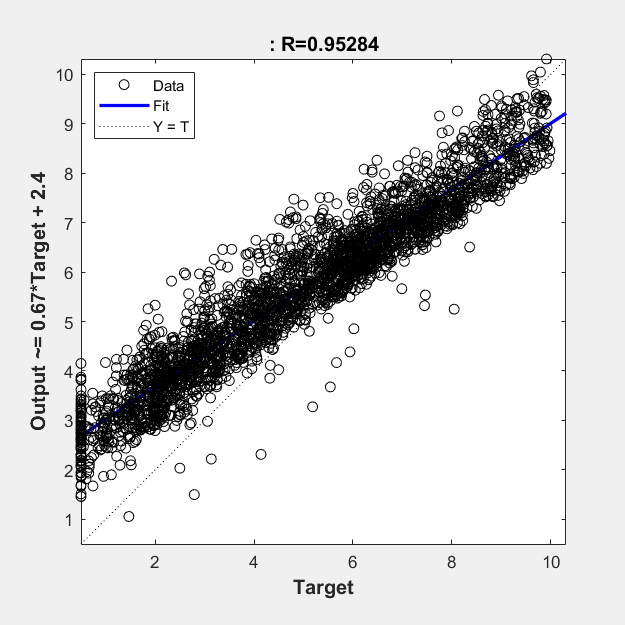


plotregression(Y_test',Y_pred);